## Exercice : Fastcore & Fastcormics on a Toy Model 

*Author : Hugues Escoffier *

clear

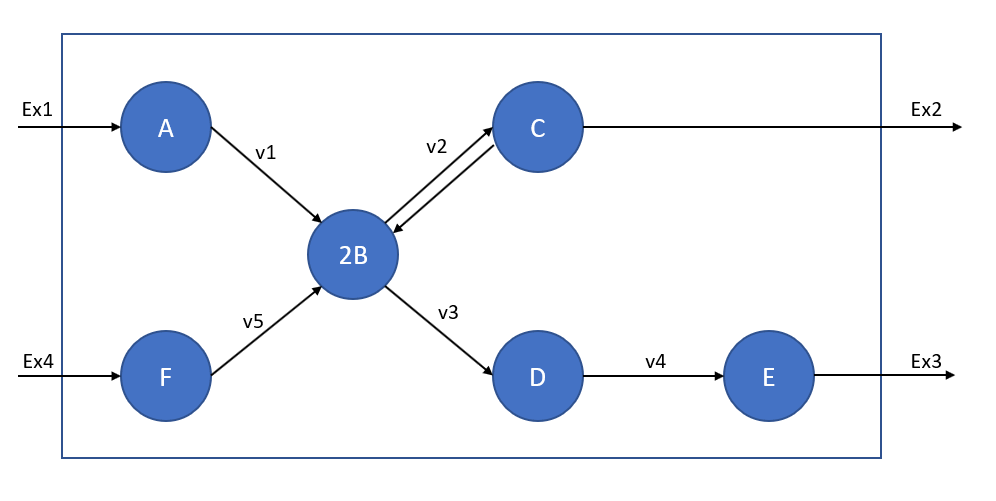

#### Question 1 : Create the model using the createModel function 

% Create model


Add the following description to your model : b

model.description = 'recon'

#### Question 2 : Is the model consistent ? 

% Enter your code here


#### Question 3: 

- 1. Find and print the exchange reactions that are importing these metabolites from the cell into the model.

% Enter your code here


 In this exercice, we want the model to be able to exchange only with the metabolites present in the medium. 

medium = {'A[c]'}

- 2. Find the reactions that are open in the model regarding the medium  

% Enter your code here


- 3. Based on the results of the previous questions, find exchanges reactions that should be unable to carry a flux and save them in a variable.

% Enter your code here


- 4. Block reactions from carrying a flux by changing the corresponding bound to 0. Then run FASTCC again on the medium constrained model. 

% Enter your code here


- 5. Run FASTCC to obtain again a medium constrained model:

% Enter your code here


#### **Question 4: **

in this part we want to mazimize the Ex3 reaction. 

- 1. Find the index for the Ex3 reaction 

% Enter your code here


- 2. Change objective 

% Enter your code here


- 3. Optimize the model to maximize the objective of the model

% Enter your code here


#### Question 5: 

- **Core reactions : v1, v3 **

Add core reactions : 

- 1. Using Fastcore

list_core_reactions = {'v1', 'v3'};

In order to run fastcore, you need a list of core reaction indexes. 

                    a. Create a list containing the cores reactions indexes (v1 and v3)

% Enter your code here


                    b. Run the fastcore() function 

**fastcore() **

Input :

- **model** : S - *m x 1* Stoichiometric matrix * lb - *n x 1* Lower bounds * ub - *n x 1* Upper bounds * rxns - *n x 1* cell array of reaction abbreviations

- **core** : Indices of reactions in cobra model that are part of the core set of reactions

- *epsilon : Smallest flux value that is considered nonzero (default 1e-4)*

- *printLevel : 0 = silent, 1 = summary, 2 = debug (default - 0)*

Output: 

- **tissueModel** : extracted model

- *coreRxnBool : n x 1 boolean vector indicating core reactions*

More informations : [https://opencobra.github.io/cobratoolbox/stable/modules/dataIntegration/transcriptomics/FASTCORE/index.html](https://opencobra.github.io/cobratoolbox/stable/modules/dataIntegration/transcriptomics/FASTCORE/index.html) 

% Enter your code here


- 2. Using Fastcormics

For fastcormircs, unlike fastcore requires a matrix in which each gene is associated with a number: 

- 0 if unknown

- 1 if expressed (core reaction)

- -1 if not expressed (inactive)

% Optional settings 
optional_settings = struct;
optional_settings.unpenalized = {};
optional_settings.func = {'Ex3'};
optional_settings.not_medium_constrained = {};

rownames = medium_constrained_consistent_model.genes; % Change according to the name of your model
dico = table(medium_constrained_consistent_model.genes, medium_constrained_consistent_model.genes); % Change according to the name of your model
biomass_rxn = 'Ex3'; 
already_mapped_tag = 0;
consensus_proportion = 1;
epsilon = 1e-4;

                    a. Create a discretize matrix based on the core reactions 

% Enter your code here


                    b. Run fastcormics_RNAseq function 

**fastcormics_RNAseq()**

Input : 

- **model **: Model use to extract the context-specific model from

- **data** : Matrix with *n* rows (1 per genes) and *m* columns (1 per sample) with 1 for expressed genes, 0 for unknown expression and -1 for unexpressed genes. 

- *rownames : The gene names for each row in the data*

- *dico :  Dictionary to map the gene names to the gene names in the model (e.g. Entrez to EnsemblID)*

- *biomass_rxn : Rxn that is (generally) to be maximized*

- *already_mapped_tag :  0 if the data has not been mapped to the GPR rules of the model, 1 otherwise*

- *consensus_proportion :  In the case where several samples are used to reconstruct a model*

- *epsilon :  Flux threshold value (1e-4)*

- *optional_settings : Structure containing 4 elements.*

Output: 

- **model** : 

- **A_final** : 

% Enter your code here


                    c. Visualize the model 

% Enter your code here
